clc; clear;close all;clf;
load direction_sf_tf_data.mat
clear orientation_direction_bayes

cell_num = 72

cell_num = 72

curve_num = 5

curve_num = 5

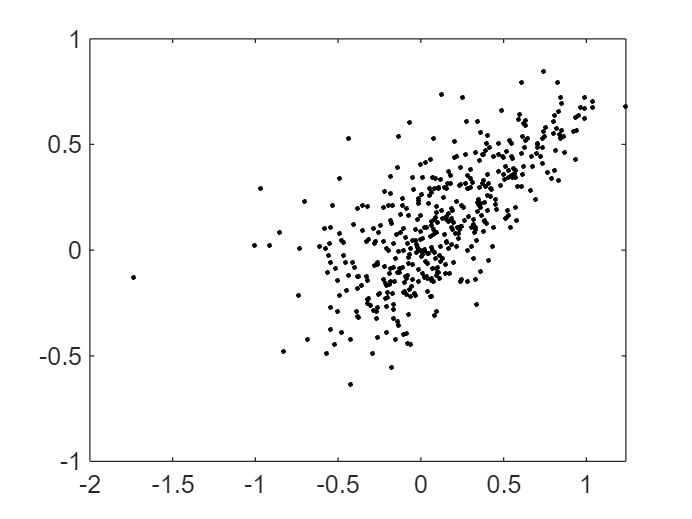

I = struct('Rp',logspace(log10(.5),log10(150),100), ...
    'Op',0:5:359, ...
    'Alpha',linspace(0,1,50), ...
    'Sig',logspace(log10(5),log10(90),10), ...
    'Rsp',logspace(log10(0.01),log10(100),5));
m = [];
v = [];
for cell_num = cell_num
    v = [v,direction_data_s{cell_num}.document_properties.stimulus_tuningcurve.response_stderr];
    m = [m,direction_data_s{cell_num}.document_properties.stimulus_tuningcurve.response_mean];
end
figure(),plot(log10(m),log10(v),'k.'),

mdl = fitlm(log10(m),log10(v)),

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________
    (Intercept)    0.076965     0.01006    7.6507     1.244e-13
    x1              0.48696    0.023814    20.448    4.7596e-66

Number of observations: 448, Error degrees of freedom: 446
Root Mean Squared Error: 0.204
R-squared: 0.484,  Adjusted R-Squared: 0.483
F-statistic vs. constant model: 418, p-value = 4.76e-66

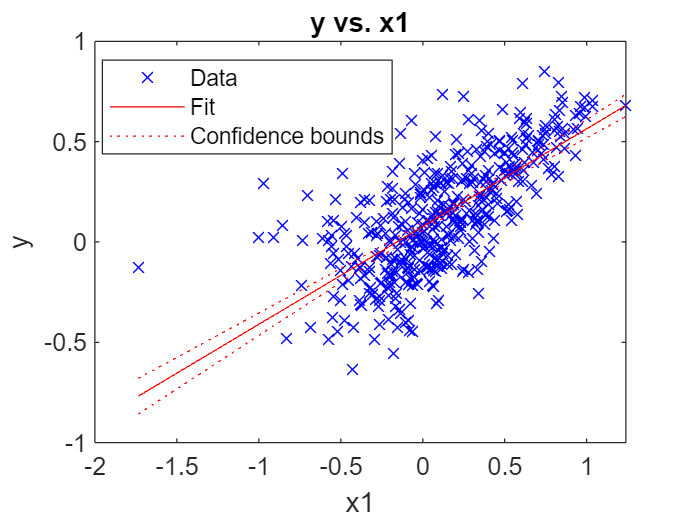

figure(),plot(mdl);

noise_coefficients = mdl.Coefficients{:,1};

data = extract_direction_data(direction_data_s{cell_num});

Unrecognized function or variable 'extract_direction_data'.

figure(),plot_dir_sf_tf(direction_data_s{cell_num});

tic;
[output,Lik] = bayes_grid_function_proportional_noise(I,data(curve_num),noise_coefficients);
toc;

plot_bayes_oridir(output)
figure(),plot(data(curve_num).angle,data(curve_num).mean_responses,'b*',0:359,output.maximum_likelihood.parameters.tunning_curve)